Q1

1(a)


$$\mathrm{Gc}\left(s\right)=K\frac{p}{z}\frac{s+z}{\;s+p},K_v =\lim_{s\longrightarrow 0} \mathrm{sGc}\left(s\right)G\left(s\right)=18$$


1(b)


$$\textrm{Gc}\left(s\right)=K\frac{s+z}{\;s+p},K_v =\lim_{s\longrightarrow 0} \textrm{sGc}1\left(s\right)\textrm{Gc}2\left(s\right)G\left(s\right)=18$$


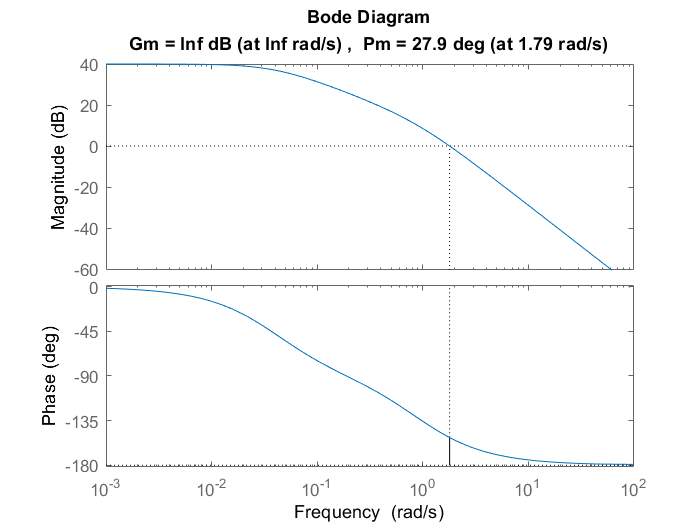

clc;clear;close all;

clc;clear;close all;
a1 = [3.6];
b1 = conv(1, [1 0.9]); b1 = conv(b1, [1 0.04]);
G = tf(a1, b1);
% figure(1); rlocus(G);
figure(2); margin(G);

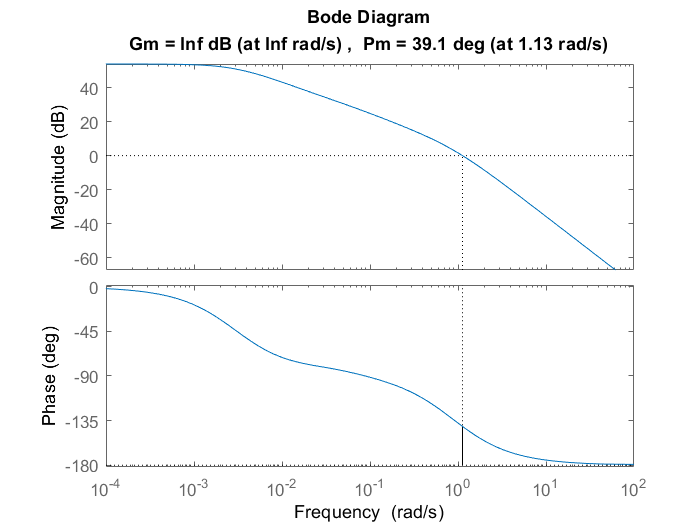


% 1a
K = 18/3.6; % make Kv = 18
omega_c = 0.334; % match PM
% omega_c: frequency when phase = PM-180+(small number)
attenuation_db = 20.9;
% attenuation_db: magnitude when frequency = omega_c
% fix omega_c then tune attenuation_db
Gca = Bode_lag(K,omega_c,attenuation_db);
La = Gca*G;
figure(3); margin(La);

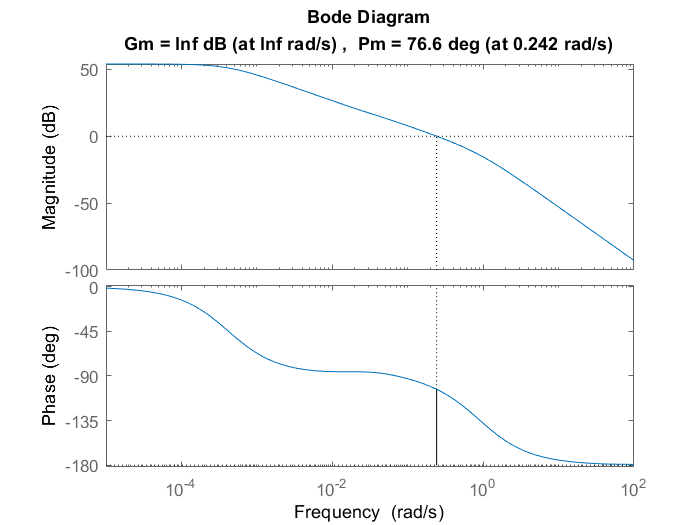


% 1a adjust
omega_c1 = 0.334; 
attenuation_db1 = 38;
Gc1a = Bode_lag(K,omega_c1,attenuation_db1);
L1a=Gc1a*G;
figure(4); margin(L1a);

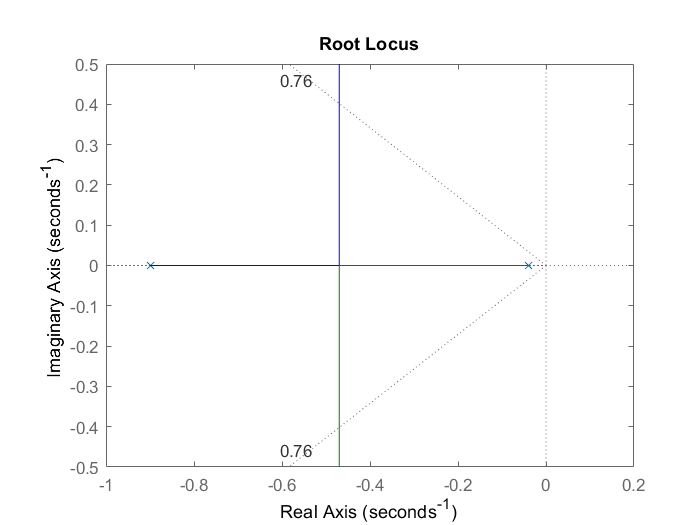


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 1b
zeta = 0.01*76;
% zeta ~ 0.01*PM for second-order system
figure(5); rlocus(G); sgrid(zeta,10^4);

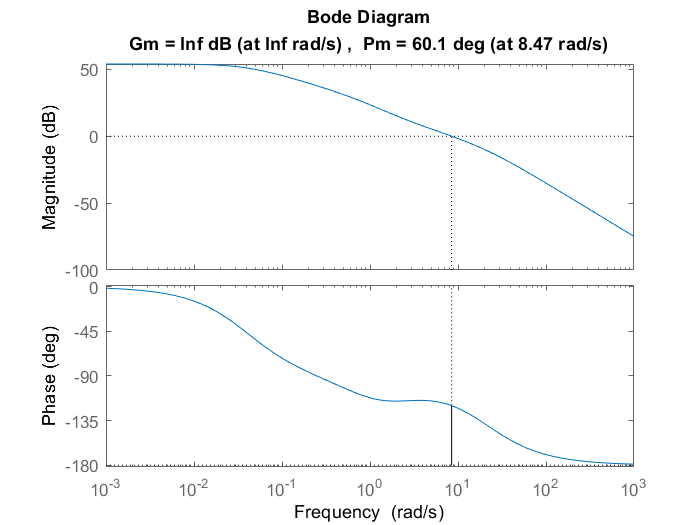

% K: gain s.t zeta <= 0.01*PM

% pull root locus left % Gc1
z1 = 2; p1 = 20; % make G as dominant poles
K1 = 18*(p1/z1)/3.6; % make Kv = 18
Gc1 = K1*tf([1 z1],[1 p1]);
L1b1 = G*Gc1;
figure(6); margin(L1b1);

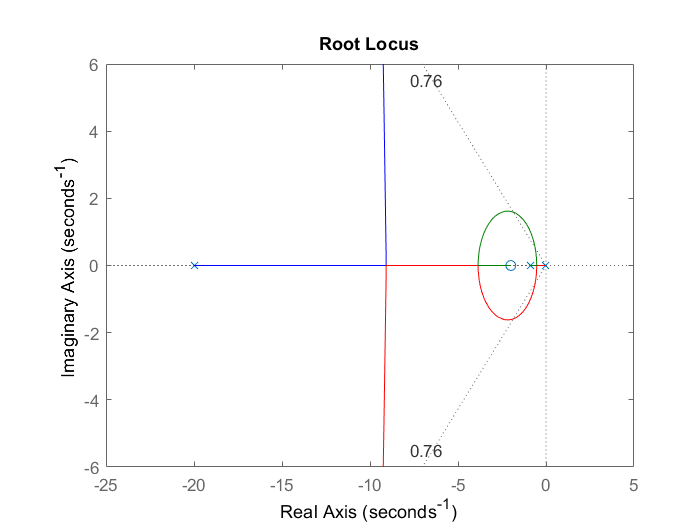

figure(7); rlocus(L1b1); sgrid(zeta,10^4);

% match ess
[~,Pm1] = margin(L1b1);
disp(['phase margin = ' num2str(Pm1)]);

phase margin = 60.1009


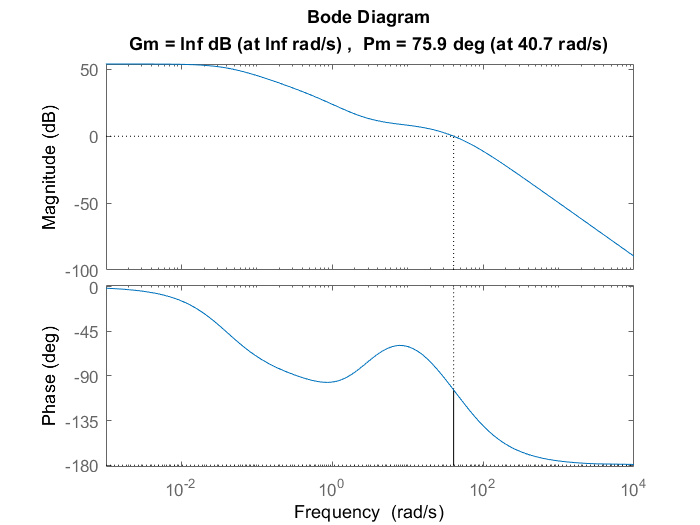


% pull root locus left % Gc2
z2 = 3.3; p2 = 60; % make G as dominant poles
K2 = p2/z2; % make Kv = 18
Gc2 = K2*tf([1 z2],[1 p2]);
L1b = G*Gc1*Gc2;
figure(8); margin(L1b);

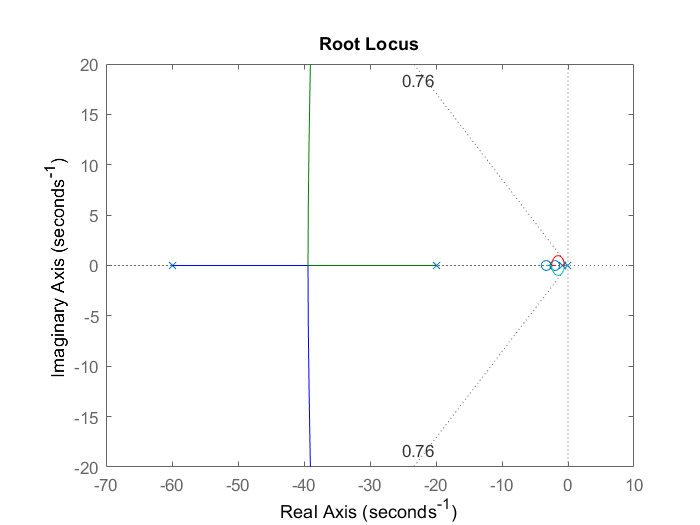

figure(9); rlocus(L1b); sgrid(zeta,10^4);

% match ess
[~,Pm1b] = margin(L1b);
disp(['phase margin = ' num2str(Pm1b)]);

phase margin = 75.908


Q2


$$G\left(s\right)=\frac{s+5}{s^3 +2s^2 +20s+3}$$



$$\textrm{Gc}\left(s\right)=K\;\frac{p}{z}\frac{s+z}{\;s+p},K_p =\lim_{s\longrightarrow 0} \textrm{Gc}\left(s\right)G\left(s\right)=30$$


clc;clear;close all;

a = [1 5]; b = [1 2 20 3];
G = tf(a, b);

% Lag + rlocus
zeta = 0.55; 
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5)

PO = 12.6324

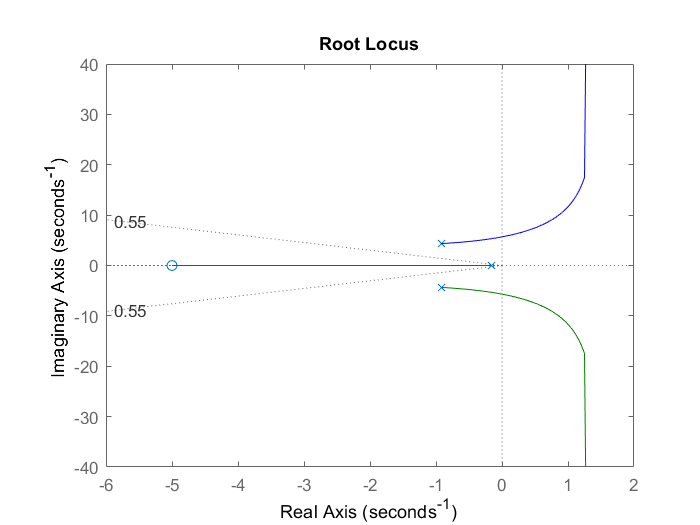

figure(1); rlocus(G); sgrid(zeta,10^4);

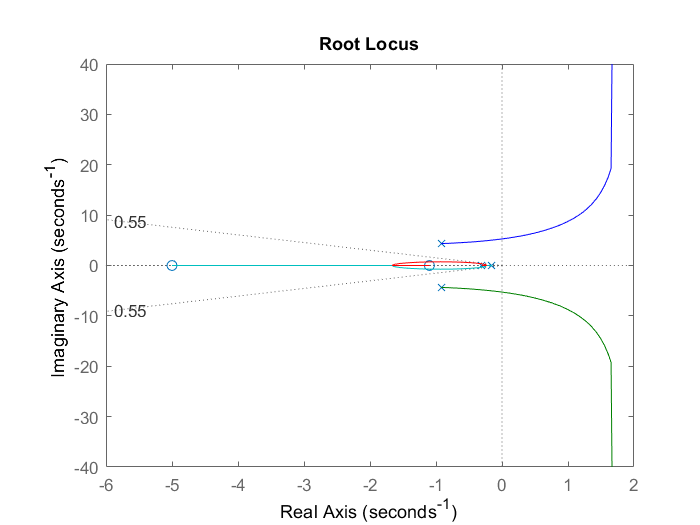


K = 5;
my_alpha = 30*(3/5)*(1/K);  %  determined by the requirement on error constant
% K*(z/p)*(5/3) = 30, my_alpha = z/p
z = 1.1;
p = z/my_alpha;
Gc = tf([1 z],[1 p]);
L = G*Gc;
figure(2); rlocus(L); sgrid(zeta,10^4);


[~,Pm]=margin(K*L);
disp(['phase margin = ' num2str(Pm)]);

phase margin = 48.535


Q3


$$G\left(s\right)=\frac{3\ldotp 6}{\left(s+0\ldotp 14\right)\left(0\ldotp 1s+1\right)}$$



$$\textrm{Gc}\left(s\right)=K\frac{p\;}{z}\frac{s+z}{\;s+p}$$


clc;clear;close all;

a = [3.6]; b = conv([1 0.14], [0.1 1]);
G = tf(a, b);

zeta = 0.6; 
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5)

PO = 9.4780

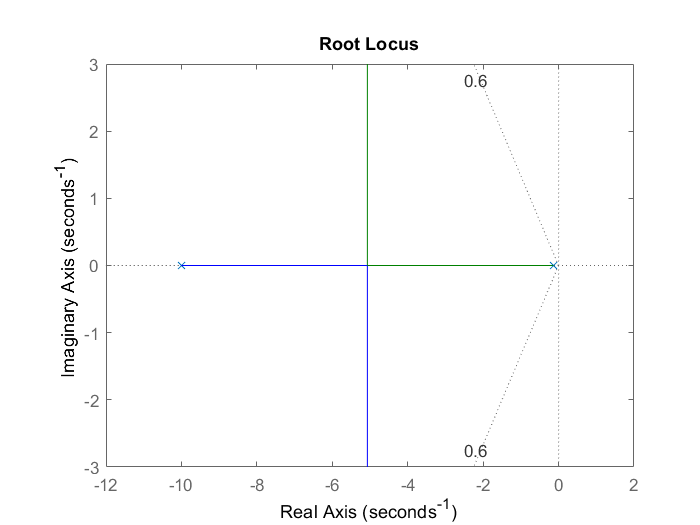

figure(1); rlocus(G); sgrid(zeta,10^4);

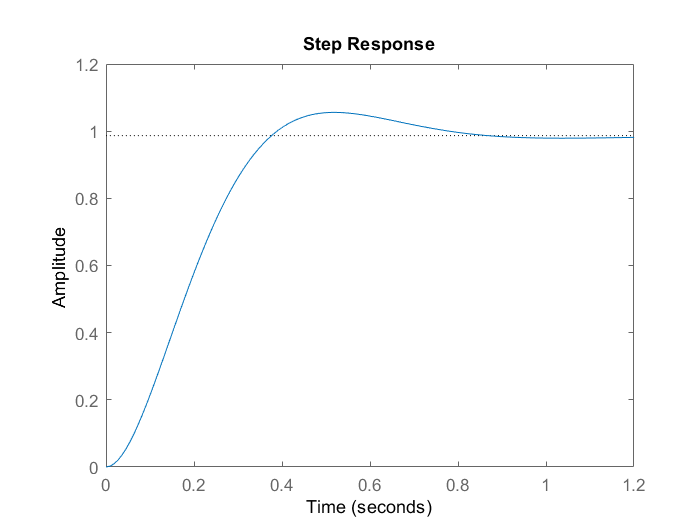


K = 1.7;  % determined by the requirement on P.M.
my_alpha = K;  %  determined by the requirement on error constant
z = 0.1; p = z/my_alpha;

Gc = tf([1 z],[1 p]); Gc = K*Gc;
L = G*Gc; 

T = feedback(L,1);
figure(2); step(T);

S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.2492
    SettlingTime: 0.7494
     SettlingMin: 0.9008
     SettlingMax: 1.0559
       Overshoot: 7.0110
      Undershoot: 0
            Peak: 1.0559
        PeakTime: 0.5198


Q4


$$G\left(s\right)=\frac{1}{\left(s-3\right)\left(s-2\right)}$$



$$\textrm{Gc}\left(s\right)=K\;\frac{s+z}{\;s+p},$$

$$\mathrm{Gp}\left(s\right)=\frac{s+z}{z}$$


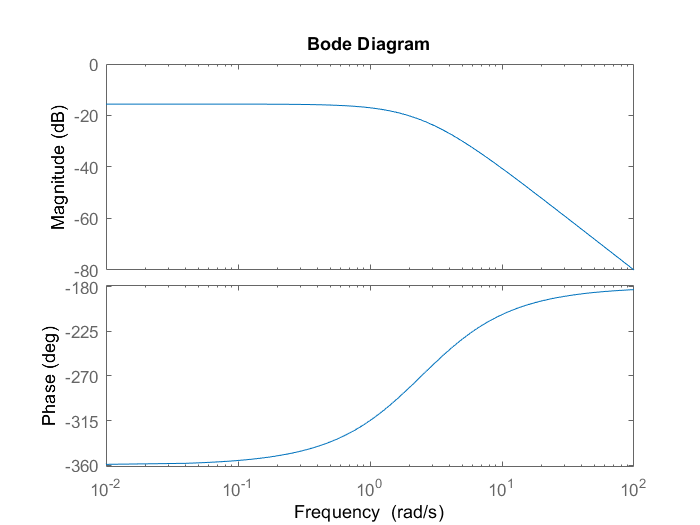

clc;clear;close all;

a = [1]; b = conv([1 -3], [1, -2]);
G = tf(a, b);
figure(1); bode(G);

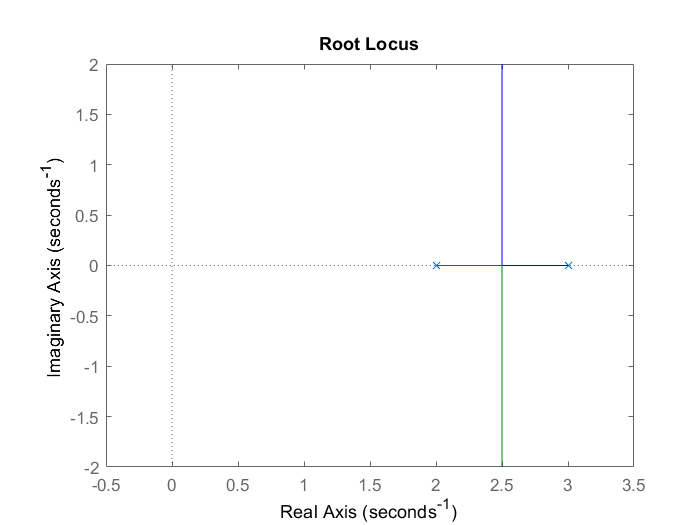

figure(2); rlocus(G);

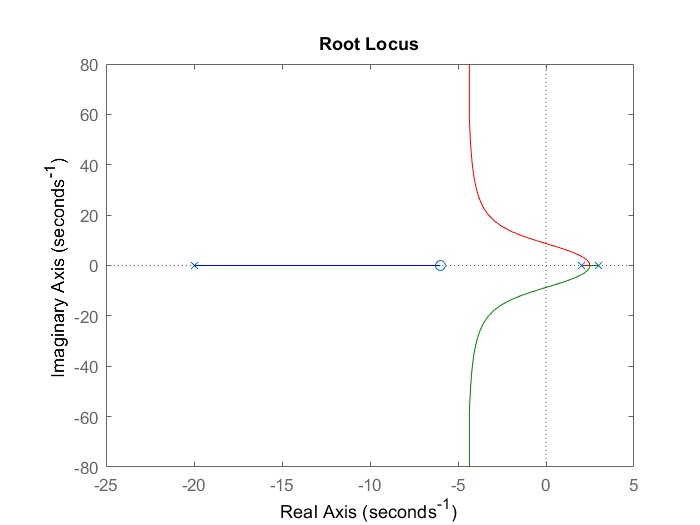


z = 6; p = 20; K = 1000;
Gc = K*tf([1 z], [1 p]);

% 4a
L1 = G*Gc; 
figure(3); rlocus(L1);

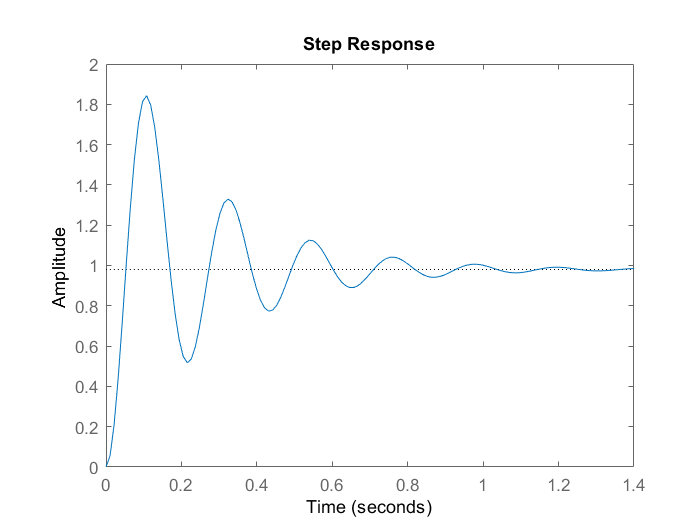

T1 = feedback(L1,1);
figure(4); step(T1);

S1 = stepinfo(T1)

S1 = struct with fields:
        RiseTime: 0.0354
    SettlingTime: 1.0028
     SettlingMin: 0.5175
     SettlingMax: 1.8425
       Overshoot: 87.9332
      Undershoot: 0
            Peak: 1.8425
        PeakTime: 0.1078


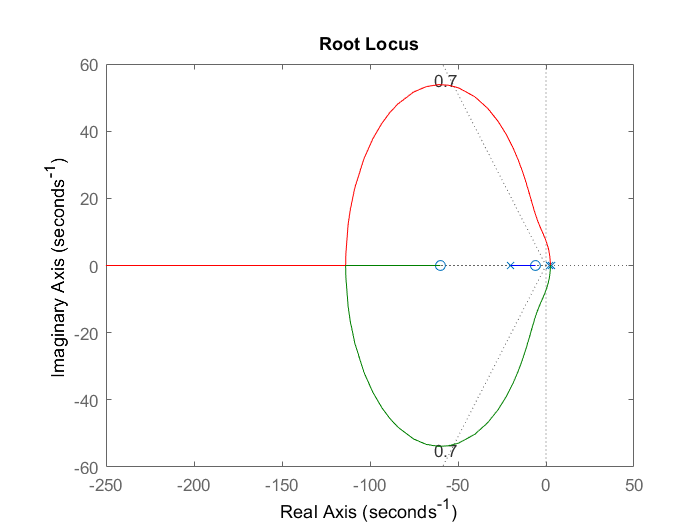


% 4b
zeta = 0.7; 
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5);
zp = 60; Kp = 100;
Gp = Kp*tf([1 zp], [zp]);
L = L1*Gp;
figure(5); rlocus(L); sgrid(zeta,10^4);

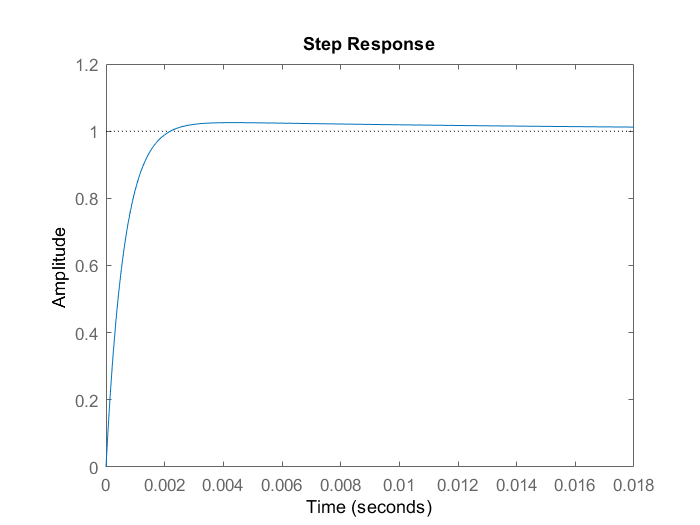


T = feedback(L,1);
figure(6); step(T);

S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.0012
    SettlingTime: 0.0093
     SettlingMin: 0.9014
     SettlingMax: 1.0254
       Overshoot: 2.5613
      Undershoot: 0
            Peak: 1.0254
        PeakTime: 0.0043


Q5


$$G\left(s\right)=\frac{1}{\left(s+0\ldotp 1\right)\left(s+4\right)}$$



$$\textrm{Gc}\left(s\right)=K\;\frac{s+z}{\;s+p},K_p =\lim_{s\longrightarrow 0} \textrm{sGc}\left(s\right)G\left(s\right)=30$$



$$\mathrm{Gp}\left(s\right)=\frac{s+z}{z}$$

$$,K_p =\lim_{s\longrightarrow 0} \textrm{sGc}\left(s\right)\mathrm{Gp}\left(s\right)G\left(s\right)=30$$


clc;clear;close all;

a = [1]; b = conv([1 0.1], [1 4]);
G = tf(a, b);

z = 5; p = 15; K = 200; 
Gc = K*tf([1 z], [1 p]); 

zeta1 = 0.45; 
PO1 = 100*exp(-zeta1*pi/(1-zeta1^2)^0.5)

PO1 = 20.5346

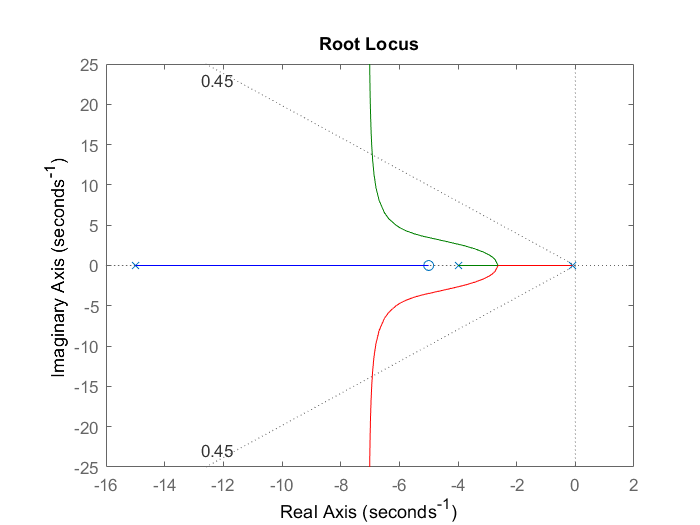


L1 = Gc*G;
figure(1); rlocus(L1); sgrid(zeta1,10^4); % --> Get K = 200

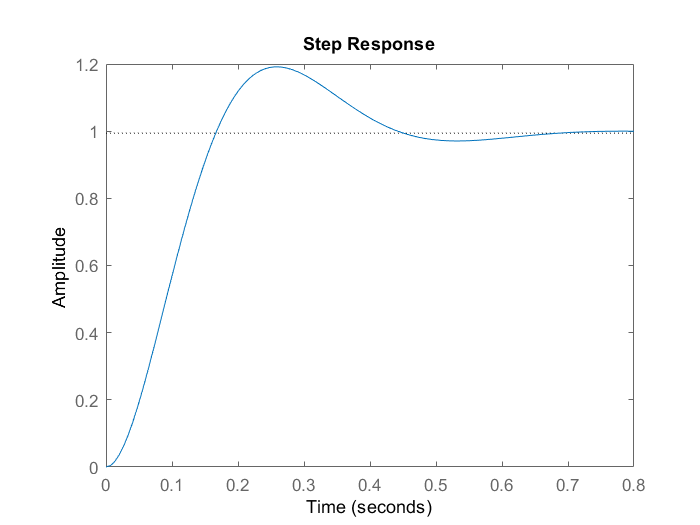

T1 = feedback(L1,1);
figure(2); step(T1);

S1 = stepinfo(T1)

S1 = struct with fields:
        RiseTime: 0.1130
    SettlingTime: 0.5719
     SettlingMin: 0.9317
     SettlingMax: 1.1915
       Overshoot: 19.8636
      Undershoot: 0
            Peak: 1.1915
        PeakTime: 0.2610



% add prefilter
zeta = 0.7; 
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5)

PO = 4.5988

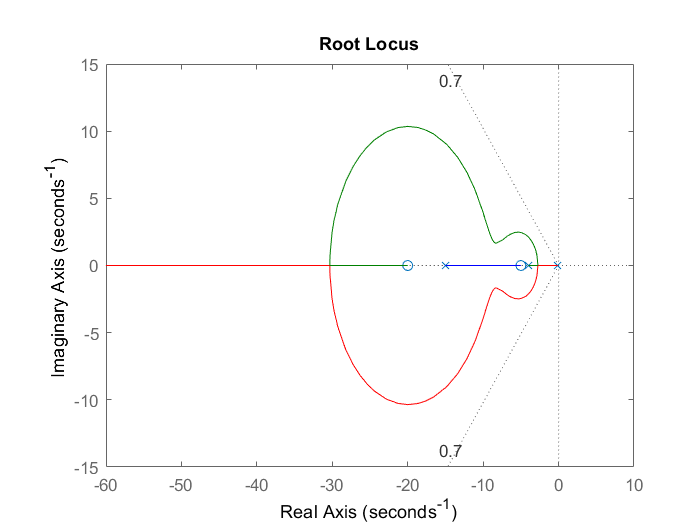


zp = 20; Kp = 16;
Gp = Kp*tf([1 zp], [zp]); 

L = L1*Gp;
figure(3); rlocus(L); sgrid(zeta,10^4); % --> Get Kp = 16

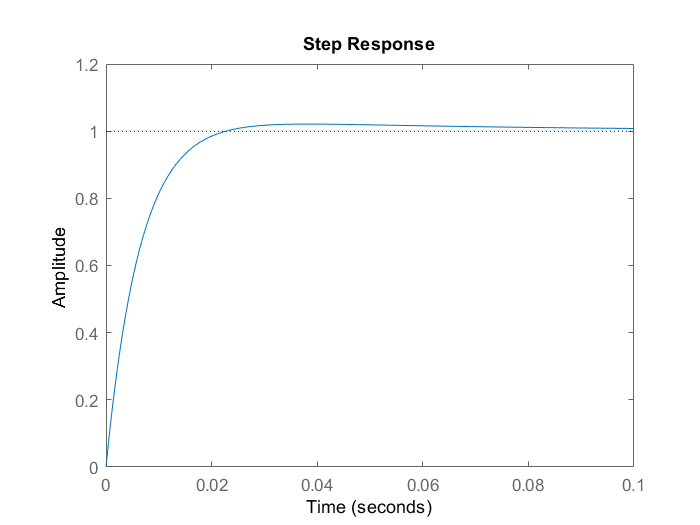

T = feedback(L,1);
figure(4); step(T);

S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.0125
    SettlingTime: 0.0472
     SettlingMin: 0.9004
     SettlingMax: 1.0211
       Overshoot: 2.1473
      Undershoot: 0
            Peak: 1.0211
        PeakTime: 0.0385


function Gc = Bode_lag(K,omega_c,attenuation_db)
    z = omega_c/10;
    alpha = 10^(attenuation_db/20);
    p = z/alpha;
    num = K*p*[1 z];
    den = z*[1 p];
    Gc = tf(num,den);
end

function [Gc] = Bode_lead(K, phi_m, wm)
    phi = phi_m*pi/180;
    a = (1+sin(phi))/(1-sin(phi));
    p = wm*(a^0.5); z = p/a;
    Gc = tf((K*(p/z)*[1 z]), [1 p]);
end